clf;
m0 = 20000;

u0 = [m0;0;0;0;0;0;0];
options = odeset('MaxStep', 1);

[T, u] = ode45(@fcn, [0 600], u0, options);


UM = u(:, 1);
UX = u(:, 2);
UY = u(:, 3);
UVx = u(:, 4);
UVy = u(:, 5);
UAlph = u(:, 6);
UOmega = u(:, 7);


subplot(2,3,1);

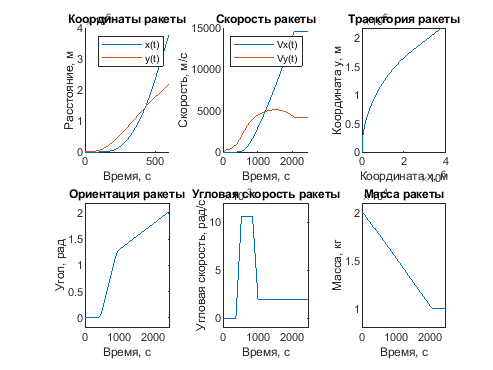

hold on;
plot(T,UX);
plot(T,UY);
title('Координаты ракеты')
xlabel("Время, c")
ylabel('Расстояние, м')
legend('x(t)', 'y(t)'); 
hold off;

subplot(2,3,2);
hold on;
plot(UVx);
plot(UVy);
title('Скорость ракеты')
xlabel("Время, c")
ylabel('Скорость, м/с')
legend('Vx(t)','Vy(t)');
hold off;

subplot(2,3,3);
plot(UX,UY);
title('Траектория ракеты')
xlabel("Координата х, м")
ylabel('Координата у, м')



subplot(2,3,4);
plot(UAlph);
title('Ориентация ракеты')
xlabel("Время, c")
ylabel('Угол, рад')
ylim([-0.2 2.2])

subplot(2,3,5);
plot(UOmega);
title('Угловая скорость ракеты')
xlabel("Время, c")
ylabel('Угловая скорость, рад/с')
ylim([-0.001 0.012])

subplot(2,3,6);
plot(UM);
title('Масса ракеты')
xlabel("Время, c")
ylabel('Масса, кг')
ylim([8000 21000])